f = @(x) x.^2-x+1;

a = 1;
b = 4;

n = 10;

I = compositeTrapezoidalRule(f, a, b, n);
disp(['The approximate integral is (Trapezoidal rule): ', num2str(I)]);

The approximate integral is (Trapezoidal rule): 16.545


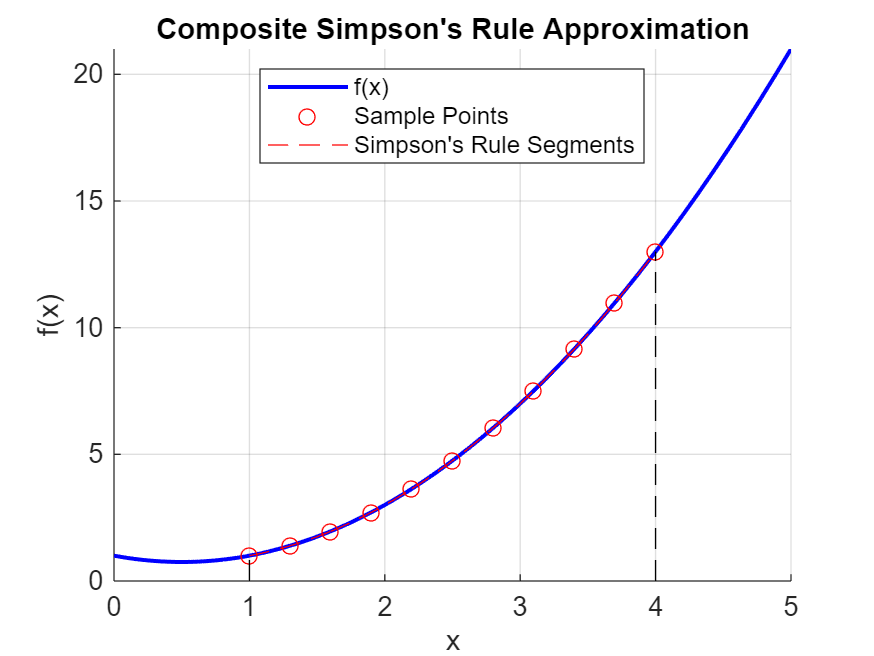

plotIntegral(f, a, b, n);


I = compositeSimpsonsRule(f, a, b, n);
disp(['The approximate integral is (Simpson rule): ', num2str(I)]);

The approximate integral is (Simpson rule): 16.5


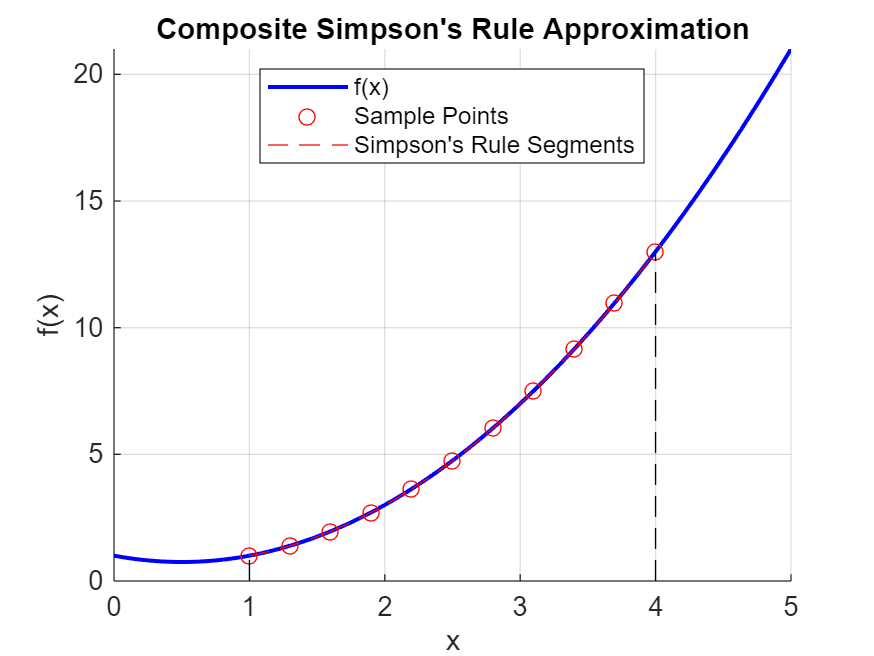

plotIntegral(f, a, b, n);

function I = compositeTrapezoidalRule(f, a, b, n)
    if n <= 0
        error('Number of subintervals n must be greater than 0.');
    end

    h = (b - a) / n;
    x = a:h:b;
    y = f(x);

    I = (h / 2) * (y(1) + y(end) + 2 * sum(y(2:end-1)));
end

function I = compositeSimpsonsRule(f, a, b, n)
    if mod(n, 2) ~= 0
        error('Number of subintervals n must be even.');
    end

    h = (b - a) / n;
    x = a:h:b;
    y = f(x);

    I = h / 3 * (y(1) + y(end) + 4 * sum(y(2:2:end-1)) + 2 * sum(y(3:2:end-2)));
end

function plotIntegral(f, a, b, n)
    if mod(n, 2) ~= 0
        error('Number of subintervals n must be even.');
    end

    h = (b - a) / n;
    x = a:h:b;
    y = f(x);
    
    figure;
    hold on;

    fplot(f, [a-1 b+1], 'b', 'LineWidth', 1.5);

    plot(x, y, 'ro');

    for i = 1:2:n-1
        xi = x(i:i+2);
        yi = y(i:i+2);
        xx = linspace(xi(1), xi(3), 100);
        p = polyfit(xi, yi, 2);
        yy = polyval(p, xx);
        plot(xx, yy, 'r--');
    end

    line([a a], [0 y(1)], 'Color', 'k', 'LineStyle', '--');
    line([b b], [0 y(end)], 'Color', 'k', 'LineStyle', '--');

    title('Composite Simpson''s Rule Approximation');
    xlabel('x');
    ylabel('f(x)');
    legend('f(x)', 'Sample Points', 'Simpson''s Rule Segments', 'Location', 'Best');
    grid on;
    ylim([0 inf]);
    hold off;
end